cd("D:\Program Files\Polyspace\R2021a\bin\win64\0\mine\GAME")
clear;clc;tic;warning off;

skill = "sb-1";
KeyOfSort = 0;
NumPlot = 20;
% 载入库EQ     # 全局变量EQ
global EQ NumEQ Enemy
EQ = readtable("data.xlsx");
EQ.Properties.RowNames=EQ.Name;
NumEQ = size(EQ,1);

% 输入参数 · 装备选择 & 敌人类型
NumShoe = 1;
m = 2;% （最多）选择 m 件装备
x = [EQ.ID(EQ.c>=3)' ones(1,4)*EQ("大书",:).ID];
Enemy.Name = "射手";
% 准备决策变量eq的所有可能 · 制定装备购买方案
eqIDList = nchoosek(x,m);% DPlan的每一行都对应着一个eq
for i=1:size(eqIDList)
    eqIDList(i,:) = sort(eqIDList(i,:),2);
end
[eqIDList, ~, ~] = unique(eqIDList,'rows');
Enemy = e0(Enemy);
%% 开始
id = 1; per=0:.1:1;ip=1; np=size(eqIDList,1);disp(np);

    67



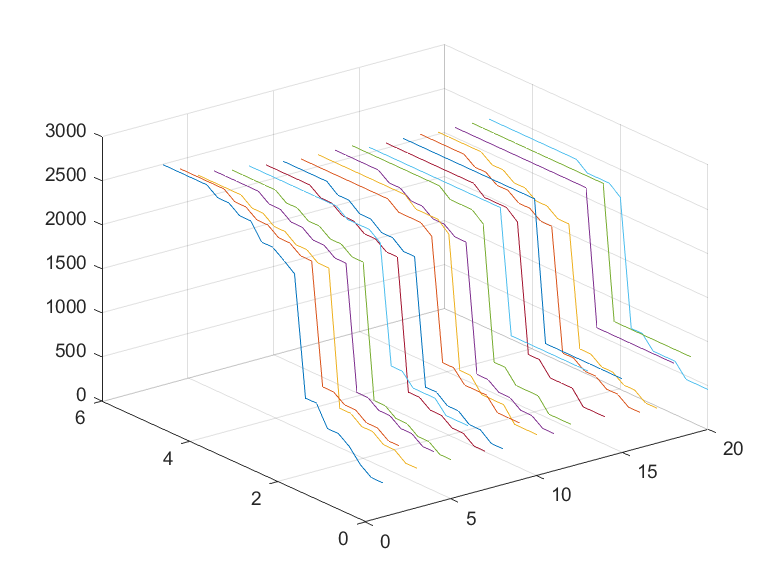

for i = 1:np
    if i > 1; id = size(Res,1)+1; end % id = id + 1;
    % 显示进度
    if np>200
        a = i/np*100/100;   % a = floor(i/np*100)/100;
        if a>=per(ip)+0/100
            disp(a);ip=ip+1;toc;
        end
    end
    eqID = [NumShoe eqIDList(i,:)];
    eq = turn(eqID);
    res = play(eqID,Enemy,skill);
    % 整理结果
    Res(id,:) = res;
    Res = mysort(Res);
    % 整理方式1
    key = KeyOfSort;
    if key < 1 && key ~= 0
        if Res(id,1).sumA < Res(1,1).sumA * key
            Res(id,:)=[];
        end
    elseif key > 1
        if id > key
            Res(id,:)=[];
        end
    end
end
% 输出格式 ` format long g
% 排序与筛选
% Result = mysort(Res);% clear Res res eqID;
% Result_0WuShu = shaixuan(Result,"巫术");
VN = {'SumA','AP','MPv','MPp','HP','CD'};
T = table(Res(i,:).sumA,Res(i,:).AP,Res(i,:).MP0(1),Res(i,:).MP0(2),Res(i,:).HP,Res(i,:).CD,'VariableNames',VN)
for i = 1:id
    T0(i,:) = [Res(i,:).sumA,Res(i,:).AP,Res(i,:).MP0(1),Res(i,:).MP0(2),Res(i,:).HP,Res(i,:).CD,];
end
% T = table(Res)
% table(Res(i,:).sumA,Res(i,:).AP,Res(i,:).MP0(1),Res(i,:).MP0(2),Res(i,:).HP,Res(i,:).CD,'VariableNames',VN)
table(T0(),'VariableNames',VN)

%% 绘制图表
rR = size(Res,1);
if rR<= NumPlot
    nr = rR;
else
    nr = NumPlot;
end
clear p;
for i=1:nr
    p(i)=plot3(ones(1,5/.25+1)*i,0:.25:5,Res(i,:).A.LeiJi(1:end-1)');
    hold on
end
grid on

toc

历时 3.007271 秒。


function ij = turn(id)
% b=[1 1 13]
global NumEQ
ij = zeros(1,NumEQ);
for i=1:NumEQ
    n=find(id==i);
    ij(i) = size(n,2);
end
end

function res = play(eqID,Enemy,skill)
% 决策变量
global EQ NumEQ Enemy
GetName = EQ.Name(eqID)';
GetName1 = GetName(1); i = 1;
while i<length(eqID)
    i = i+1;
    GetName1 = string(GetName1) + ' ' + string(GetName(i));
end
% 决策变量mw cd· Inscriptions 铭文	r	b 10狩猎	g 10心眼
I.AP = 0;
I.MP = 88;
I.ew = 0;
I.cd = 0;% cool down (time)
CD.I = I.cd;
CD.b = 0;
% 信息
self.AP = 0;
self.ew = 0;
WC=0;
WCR=0;
MP=0;
lv = 15;
% 装备；Equipments, Outfit
eq = turn(eqID);
res.eq = eq;
res.OneName = GetName1;
% res.GetName = string(GetName);
%% 约束条件
[Skill,CD] = Sk(skill,CD);

HitTime1 = [];
% 计算 装备特效 伤害总量
dt = .25; tend = 5;
Numdt = tend/dt+1;
t_all = 1:Numdt;
MP_e(t_all,1)=I.MP*ones(Numdt,1);% MP_each
% EQ = readtable("data.xlsx");
ob_all=1:1:NumEQ;
% 初始化
tofree(t_all,ob_all) = 0;
global xg
xg(t_all,ob_all) = 0;
d.xg(t_all,ob_all) = 0;

type_skill = ones(1,Skill.duan*2)*(2);
type_xg = EQ.Type'; % f_2 (EQ);
type = [type_skill, type_xg];
global td
key.buff = 0;
for t = 0:dt:tend
    td = t/dt+1;% =td
    % eq_change==0
    eq(td,:)=eq(1,:);
    % 装备面板属性累加
    AP0.EQ(td) = sum(eq(td,:).*EQ.AP');
    AD0.EQ(td) = sum(eq(td,:).*EQ.AD');
    AD(td) = AD0.EQ(td);
    CD.E(td) = sum(eq(td,:).*EQ.CD');
    if key.buff == 0
        CD.s(td) = CD.b+CD.I+CD.E(td);
    end
    CD.r(td) = CD.s(td)+ceil((CD.s(td)-.4)/9)*(.4-CD.s(td));% CD上限为0.4
    HP0.EQ(td) = sum(eq(td,:).*EQ.HP');
    if ismember(t,Skill.HitTime)==1
        hit(td)=1;
    else hit(td)=0;
    end
    if ismember(t,HitTime1)==1
        hit1(td)=1;
    else hit1(td)=0;
    end
    % 命中
    for ob = 1:NumEQ
        if eq(td,ob)>=1
            if tofree(td,ob)==0
                switch EQ.cata(ob)
                    case 0
                        xg(td,ob)=1;
                    case 1
                        if hit(td)==1
                            if EQ.CDConsist(ob)==0% 如果它是瞬发的
                                xg(td,ob)=1;
                            else
                                i1=td+EQ.CDin(ob)/dt:EQ.CDin(ob)/dt:td+EQ.CDConsist(ob)/dt;
                                xg(i1,ob)=1;
                            end
                            tofree(td:td+EQ.CDRange(ob)/dt,ob)=1;
                        end
                    case 2
                        if hit1(td)==1
                            if EQ.CDConsist(ob)==0% 如果它是瞬发的
                                xg(td,ob)=1;
                            else
                                i1=td+EQ.CDin(ob)/dt:EQ.CDin(ob)/dt:td+EQ.CDConsist(ob)/dt;
                                xg(i1,ob)=1;
                            end
                            tofree(td:td+EQ.CDRange(ob)/dt,ob)=1;
                        end
                end
            end
        end
    end
    %% 令xg生效
    %     [AP]()
    %% 被动·级别1
    [ef j]= f(td,"帽子");
    % ef为有无，j为ID
    a=.3;
    AP(td )=(I.AP+AP0.EQ(td))*(1+eq(td,j)*a);
    %% 主动·级别2·鞋子
    [ef j]= f(td,"法穿鞋");
    if ef==1
        a=5; b=45;
        % magic penetration
        MP_e(td,2)=a*lv+b;% 铭文 法穿鞋 日暮
    else
        MP_e(td,3)=0;
    end
    %% 主动·级别2·法术
    [ef j]= f(td,"回响");
    if ef==1
        a=.4; b=100;
        d.xg(td,j) = a*AP(td)+b;
    end
    [ef j]= f(td,"面具");
    if ef==1
        a=.03;
        d.xg(td,j) = Enemy.HP(td)*a;
    end
    [ef j]= f(td,"冰杖");
    if ef==1
        a=400;
        d.xg(td,j) = a;
    end
    [ef j]= f(td,"巫术");
    if ef==1
        a=.7;
        d.xg(td,j) = a*AP(td)+(1-a)*AD(td);
    end
    [ef j]= f(td,"金剑");
    if ef==1
        a=.3;
        d.xg(td,j) = a*AP(td);
    end
    [ef j]= f(td,"日暮");
    if ef==1
        a=[14 28]; c=10;
        cs = c;
        % 可进一步！
        % magic penetration
        MP_e(td,3)=a(2)*cs;% 铭文 法穿鞋 日暮
    else
        MP_e(td,3)=0;
    end
    [ef j]= f(td,"法穿杖");
    if ef==1
        a=.45;
        MPR(td,1)=a;% 铭文 法穿鞋 日暮
    else
        MPR(td,1)=0;
    end
    [ef j]= f(td,"大书");
    if ef==1
        a=.12; b=100; c=1500;
        k = a*b/c;
        r = floor(AP(td)/b)*k;
        if r>a
            r=a;
        end
        k_zs(td,1)=r;
    else
        k_zs(td,1)=0;
    end
    %% 主动·级别2·物理
    [ef j]= f(td,"破军");
    if ef==1 && Enemy.HP(td)<=.5*Enemy.MaxHP
        a=.3;
        k_zs(td,2)=a;
    else
        k_zs(td,2)=0;
    end
    %% 主动·级别2·防具
    [ef j]= f(td,"爆裂甲");
    if ef==1
        a=.02; b=5;
        cs = b;
        % 可进一步！
        k_zs(td,3)=a*cs;
    else
        k_zs(td,3)=0;
    end
    %% 主动·级别2·打野
    [ef j]= f(td,"大黄刀");
    if ef==1
        a=3; b=30; cs=b;
        d.xg(td,j) = a*cs;
    end
    % 令技能的伤害生效
    % 基础伤害；法术加成（属性加成）；sum
    ans = zeros(3,Skill.duan);	% 初始化
    h=intersect(t,Skill.HitTime);
    if isempty(h)==0	% 若此时技能命中
        j = find(Skill.HitTime==h);%第几段
        ans(1,j) = Skill.a_base(j)+Skill.x_lv*Skill.k_lv(j);
        ans(2,j) = Skill.k_AP(j)*AP(td);
        ans(3,:) = sum(ans(1:2,:),2);
    end

    % 统计

    k_zs_sum(td)=sum(k_zs(td,:));
    MP(td)=sum(MP_e(td,:));
    % MPR;
    d.skill_Base(td,:)=ans(1,:);
    d.skill_Enhance (td,:)=ans(2,:);
    d.skill_Each(td,:) = [d.skill_Base(td,:), d.skill_Enhance(td,:)];
    d.skill_Sum(td)=sum(d.skill_Each(td,:));
    d.All_0(td,:)=[d.skill_Each(td,:), d.xg(td,:)];
    d.All(td,:)=d.All_0(td,:)*(1+k_zs_sum(td));
    chuantou(td,:) = [WC,WCR,MP(td),MPR(td)];
    global sum_a
    [Accept(td,:) sum_A(td,1)]= f_3(d.All(td,:),type,chuantou(td,:));
end
% Table.skill = [d.skill_Base,d.skill_Enhance,d.skill_Sum'];
% Table.skill(td+1,:) = sum(Table.skill,1);
a = Skill.duan*2;
Table.Give = [d.All;sum(d.All,1)];
Table.Give = [Table.Give,sum(Table.Give,2)];
G_skill = Table.Give(:,1:a);
G_xg = Table.Give(:,a+1:end-1);
G_sum = Table.Give(:,end);
G = table(G_skill,G_xg,G_sum);
Table.Accept = [Accept;sum(Accept,1)];
Table.Accept = [Table.Accept,sum(Table.Accept,2)];
A_skill = Table.Accept(:,1:a);
A_skills = sum(A_skill,2);
A_skill_base = sum(A_skill(:,[1 2]),2);
A_skill_enhance = sum(A_skill(:,[3 4]),2);
A_xg = Table.Accept(:,a+1:end-1);
A_xgs = sum(A_xg,2);
A_sum = Table.Accept(:,end);
A = table(A_skill_base,A_skill_enhance,A_skills,A_xg,A_xgs,A_sum);
A.LeiJi=zeros(td+1,1);
for i=1:td
    if i==1
        A.LeiJi(i,1)=A_sum(i);
    else
        A.LeiJi(i,1)=A_sum(i)+A.LeiJi(i-1);
    end
end
res.A = A;
res.sumA = Table.Accept(end);
res.per = [A_skill_base(end) A_skill_enhance(end) A_xgs(end)] /res.sumA;
b = Table.Accept(end,1:end-1);
res.ptype = round([sum(b(type==1)) sum(b(type==2)) sum(b(type==3))]);
res.G = G;
res.sumG = Table.Give(end);
res.AP = mean(AP);
res.MP0 = mean(chuantou(:,[3 4]));
res.HP = mean(HP0.EQ);
res.CD = mean(CD.r);
end

function [accept sum_a] = f_3 (damage,type,chuantou)
global td Enemy
nj=length(type);
% for i=1:td
for j=1:nj
    switch type(j)
        case 3
            accept(j)=damage(j);
        case 2
            a = 602;
            b = ceil((Enemy.fk-chuantou(3))/9999);% whether Enemy.fk > d.fc
            yxfk = (Enemy.fk-chuantou(3)) *b*(1-chuantou(4));  % youxiaofakang
            bili = (a/(a+yxfk)) * (1-Enemy.ms);
            % ms = 1-bili ;
            RecvMagic = damage(j) * bili ;
            accept(j) = RecvMagic;
        case 1
            a = 602;
            b = ceil((Enemy.fk-chuantou(1))/9999);% whether Enemy.fk > d.fc
            yxwk = (Enemy.fk-chuantou(1)) *b*(1-chuantou(2));  % youxiaofakang
            bili = (a/(a+yxwk)) * (1-Enemy.ms);
            % ms = 1-bili ;
            Recvp = damage(j) * bili ;
            accept(j) = Recvp;
    end
end
sum_a = sum(accept);
Enemy.HP(td+1) = Enemy.HP(td) - sum_a;
if Enemy.HP(td+1)>0
    str = "生存";
else str = "死亡";
end
Enemy.kill(td+1) = str;
end

function [ef,id]=f(td,str)
global xg EQ
id = find(EQ.Name==str);
ef = xg(td,id);
end

function Output = mysort(Input,whom)
% 取整了伤害总值
% ? whom
for i = 1:size(Input,1);
    Input(i).sumA = round(Input(i).sumA);
    Input(i).sumG = round(Input(i).sumG);

    According(i,1) = Input(i).sumA;
end
[D,I] = sort(According,'descend');
Output = Input(I,:);
end

function Out = shaixuan(In,who)
global EQ
ids = find(EQ.Name==who);
id = 1;
for i = 1:size(In,1);
    if In(i).eq(ids)==0
        pick(id) = i;
        id = id+1;
    end
end
Out = In(pick,:);
end


Enemy All

function Enemy = e0(Enemy,p)
% if exist('n')==1 && n=="战士"
%     Enemy.name = '400,8285' ;
%     Enemy.fk = 400;
%     Enemy.HP = 8285;
%     Enemy.MaxHP = 8285;
%     Enemy.ms = 0;
%     e = ee(e) ;
if Enemy.Name=='射手'
    % nemy.name = '射手' ;
    Enemy.fk = 160;
    Enemy.HP = 6000;
    Enemy.MaxHP = 6000;
    Enemy.ms = 0;
end
Enemy.kill = "生存";
if exist("p","var")==1
    Enemy.HP = Enemy.HP*p;
end
end

function [Skill,CD] = Sk(skill,CD)
if skill == "sb-1"
    % 孙膑的一技能
    Skill.Name="sb-1";
    Skill.a_base=[180 540];
    Skill.k_lv=[40 135];
    Skill.k_AP=[.18 .54];
    Skill.k_AP_sum = sum(Skill.k_AP);
    Skill.x_lv=6;
    Skill.duan=2;
    % kz.JianSu = .4; % 控制 减速,.4，2s
    Skill.HitTime = [0 2];
    CD.b = .2;
end
end